t0 = day_to_sec(0); % Departure time
ToF = day_to_sec(11); % Time of flight for transfer

% Calculate the transfer angle, TA, for the transfer (change in true anomaly along transfer orbit)
theta_1 = propagate_conic_kep(planet_g, star.mu, t0) + planet_g.w; % Initial latitude
theta_2 = propagate_conic_kep(planet_h, star.mu, t0 + ToF) + planet_h.w; % Final latitude
TA = wrapTo2Pi(theta_2 - theta_1); % [rad] Make sure we get the right angle by using wrap function
fprintf(sprintf("Transfer Angle is %.3f degrees", rad2deg(TA)))

Transfer Angle is 217.357 degrees

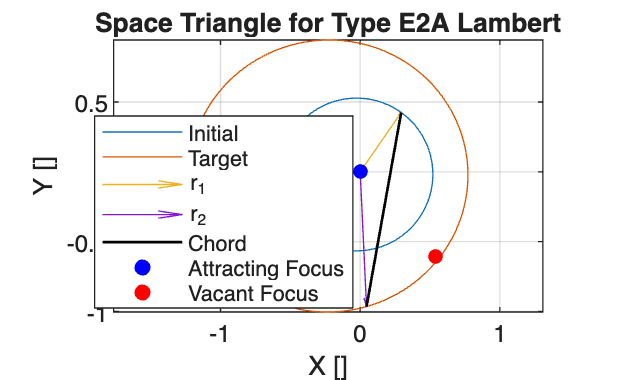

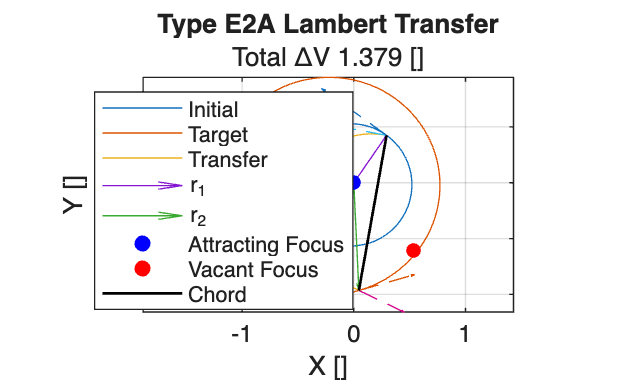

% Calculate initial radius and final orbital radius
r_1 = planet_g.a * (1 - planet_g.e ^ 2) / (1 + planet_g.e * cos(theta_1 - planet_g.w));
r_2 = planet_h.a * (1 - planet_h.e ^ 2) / (1 + planet_h.e * cos(theta_2 - planet_h.w));
% Define initial orbit (minus) and final orbit (plus)
minus_orbit_info.a = planet_g.a / star.l;
minus_orbit_info.e = planet_g.e;
minus_orbit_info.w = planet_g.w;
minus_orbit_info.ascension = sign(wrapToPi(theta_1 - planet_g.w)); % Is on ascending half of orbit or descending half?
plus_orbit_info.a = planet_h.a / star.l;
plus_orbit_info.e = planet_h.e;
plus_orbit_info.w = planet_h.w;
plus_orbit_info.ascension = sign(wrapToPi(theta_2 - planet_h.w)); % Is on ascending half of orbit or descending half?

% Calculate transfer
[a, lambert_type, space_triangle_info, transfer_info, lambert_solve_info, minus_orbit_info, plus_orbit_info] = lambert_arc(r_1 / star.l, r_2 / star.l, TA, ToF / star.t, minus_orbit_info, plus_orbit_info);

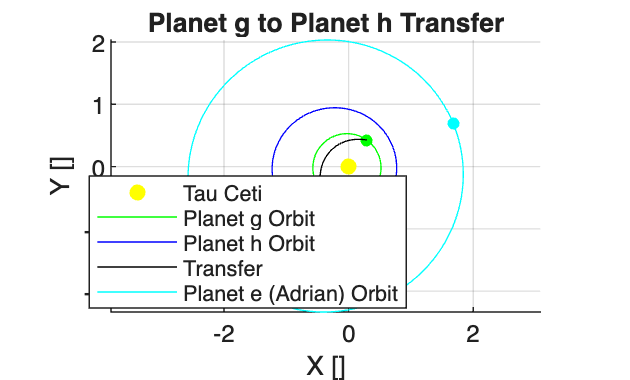

% Plot using our names

% Plot new locations
% Initialize 2D Figure
figure;
hold on;
grid on;
axis equal;

% Plot Tau Ceti at origin
scatter(0, 0, 36, 'y', 'filled', DisplayName = "Tau Ceti");

orbitplot2D(planet_g.a, planet_g.e, thetastar + transfer_info.maneuver_1.thetastar(1), planet_g.w, "Planet g Orbit", color = "g", r_scale = star.l, Marker = "o", MarkerSize = 4)
orbitplot2D(planet_h.a, planet_h.e, thetastar + transfer_info.maneuver_2.thetastar(2), planet_h.w, "Planet h Orbit", color = "b", r_scale = star.l, Marker = "o", MarkerSize = 4)
orbitplot2D(transfer_info.a, transfer_info.e, linspace(transfer_info.maneuver_1.thetastar(2), transfer_info.maneuver_1.thetastar(2) + TA, 200), transfer_info.w, "Transfer", color = "k")
orbitplot2D(planet_e.a, planet_e.e, thetastar + planet_e.theta_star, planet_e.w, "Planet e (Adrian) Orbit", color = "c", r_scale = star.l, Marker = "o", MarkerSize = 4)

% Labels and Formatting
xlabel('X []');
ylabel('Y []');
title('Planet g to Planet h Transfer');
legend('Location', 'best');
hold off;